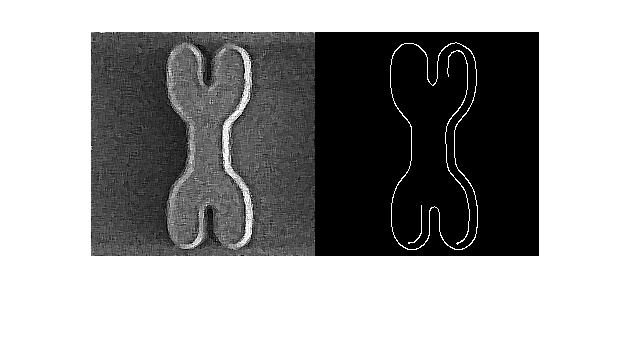

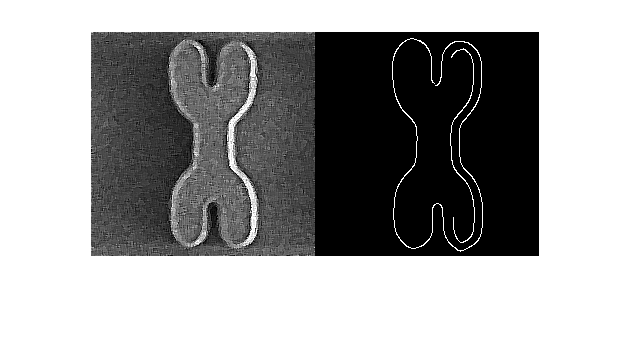

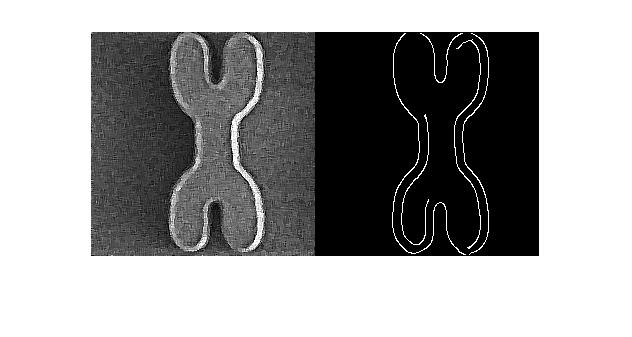

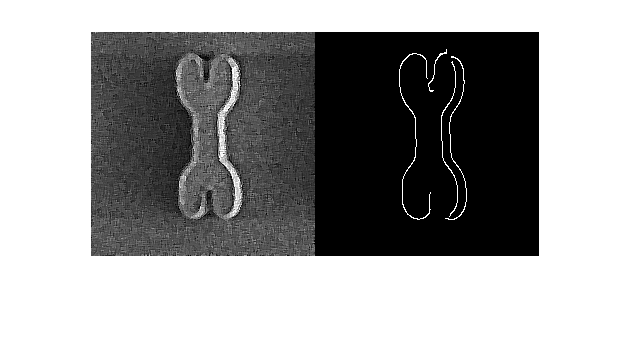

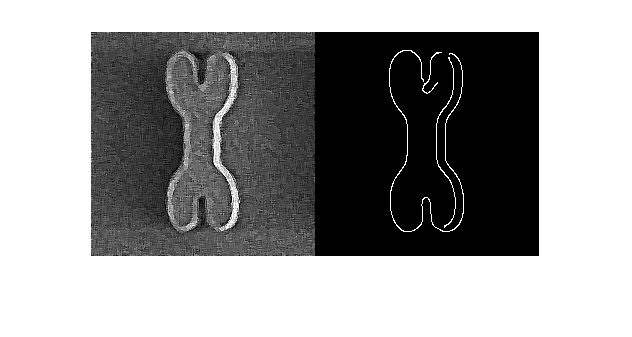

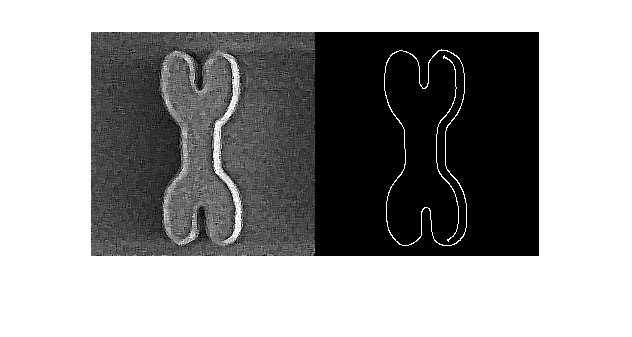

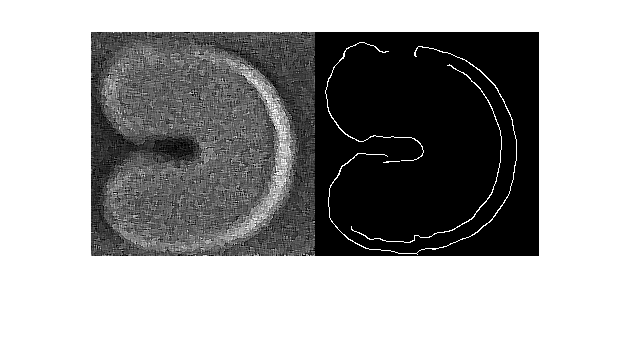

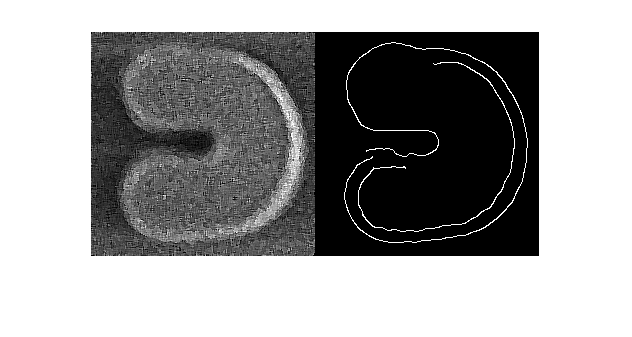

% Specify the folder where the files live.
myFolder = 'F:\Stanford\CS230-Deep_Learning\Project\images';
% Specify output folder for images processed with Canny edge detector. Make
% sure the folder is created beforehand.
outFolder = 'F:\Stanford\CS230-Deep_Learning\Project\images-Canny';
% Check to make sure that folder actually exists.  Warn user if it doesn't.
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
% Get a list of all files in the folder with the desired file name pattern.
filePattern = fullfile(myFolder, '*.png'); % Change to whatever pattern you need.
theFiles = dir(filePattern);
for k = 1 : length(theFiles)
    baseFileName = theFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    img = imread(fullFileName);
    % Convert to binary image
    img_bw = rgb2gray(img);
    % Apply Canny edge detection
    BW1 = edge(img_bw,'Canny', [0.1 0.5], 4);
    figure;
    imshowpair(img, BW1, 'montage');
    newName = strrep(baseFileName,'.png','-');
    outFilename = strcat(newName, 'Canny.png');
    fullOutName = fullfile(outFolder, outFilename);
    imwrite(BW1, fullOutName);
end